# Advanced source reconstruction using DIPFIT/Fieldtrip

This Live Script shows how to use the Fieldtrip's DIPFIT plugin with EEGLAB to perform EEG source modeling in a volume and on a surface

## Set up environment

Load data in eeglab and relevant plugins:

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is ~/eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one


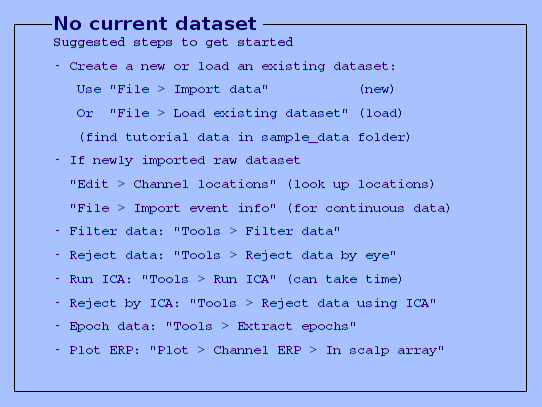

Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "Fieldtrip-lite" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "Fileio" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ICLabel" v1.2.6 (see >> help eegplugin_iclabel)
EEGLAB: adding "MFFMatlabIO" v3.5 (see >> help eegplugin_mffmatlabio)
EEGLAB: adding "bva-io" v1.6 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.2 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v3.0 (see >> help eegplugin_dipfit) - new version 3.4 available
EEGLAB: adding "firfilt" v2.1 (see >> help eegplugin_firfilt) - new version 2.4 available
EEGLAB: adding "musemonitor" v3.1 (see >> help eegplugin_musemonitor) - new version 3.2 available
You are using the latest version of EEGLAB.


eeglab                        % start eeglab

eeglabPath = fileparts(which('eeglab'));                 % save its location
bemPath = fullfile(eeglabPath, 'plugins', 'dipfit', 'standard_BEM');    % load the dipfit plug-in
EEG = pop_loadset(fullfile(eeglabPath, 'sample_data', 'eeglab_data_epochs_ica.set'));   % load the sample eeglab epoched dataset

pop_loadset(): loading file /home/claire/Applications/eeglab/sample_data/eeglab_data_epochs_ica.set ...
Reading float file '/home/claire/Applications/eeglab/sample_data/eeglab_data_epochs_ica.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


To localize sources EEG data, we first need to use DIPFIT to align the electrode locations with a head model:  

EEG = pop_dipfit_settings( EEG, 'hdmfile',fullfile(bemPath, 'standard_vol.mat'), ...
           'coordformat','MNI','mrifile',fullfile(bemPath, 'standard_mri.mat'), ...
           'chanfile',fullfile(bemPath, 'elec', 'standard_1005.elc'), ...
           'coord_transform',[0.83215 -15.6287 2.4114 0.081214 0.00093739 -1.5732 1.1742 1.0601 1.1485] , ...
         'chansel',[1:32] );

## Source reconstruction in a volume

### Calculate leadfield matrix

We then calculate a volumetric leadfield matrix using the Fieldtrip function *ft_prepare_leadfield*.

The head model is also used to assess whether a given voxel is within or outside the brain.

  %% Leadfield Matrix calculation
dataPre = eeglab2fieldtrip(EEG, 'preprocessing', 'dipfit');   % convert the EEG data structure to fieldtrip

Transforming electrode coordinates to match head model



cfg = [];
cfg.channel = {'all', '-EOG1'};
cfg.reref = 'yes';
cfg.refchannel = {'all', '-EOG1'};
dataPre = ft_preprocessing(cfg, dataPre);

 In fixsampleinfo at line 88
 In ft_datatype_raw at line 149
 In ft_checkdata at line 267
 In ft_preprocessing at line 289



> In fixsampleinfo (line 102)
  In ft_datatype_raw (line 149)
  In ft


vol = load('-mat', EEG.dipfit.hdmfile);

cfg            = [];
cfg.elec       = dataPre.elec;
cfg.headmodel  = vol.vol;
cfg.resolution = 10;   % use a 3-D grid with a 1 cm resolution
cfg.unit       = 'mm';
cfg.channel    = { 'all' };
[sourcemodel] = ft_prepare_leadfield(cfg);

using electrodes specified in the configuration
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
creating sourcemodel based on automatic 3D grid with specified resolution
using electrodes specified in the configuration
creating 3D grid with 10 mm resolution
initial 3D grid dimensions are [21 24 21]
2015 dipoles inside, 8569 dipoles outside brain
making tight grid
2015 dipoles inside, 2035 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 1 seconds and required the additional allocation of an estimated 0 MB
computing leadfield
computing leadfield 2015/2015

the call to "ft_prepare_leadfield" took 6 seconds and required the additional allocation of an estimated 0 MB


### Perform source reconstruction

We are now using the generated leadfield matrix to perform source reconstruction. 

We show here a simple example using eLoreta to model putative sources of ERP features.

First, compute an ERP in Fieldtrip. Note that the covariance matrix needs to be calculated for ue in source estimation

cfg                  = [];
cfg.covariance       = 'yes';
cfg.covariancewindow = [EEG.xmin 0]; % calculate the average of the covariance matrices
                                   % for each trial (but using the pre-event baseline  data only)
dataAvg = ft_timelockanalysis(cfg, dataPre);

the input is raw data with 31 channels and 80 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_timelockanalysis" took 1 seconds and required the additional allocation of an estimated 1 MB


Now do the source reconstruction:

cfg             = [];
cfg.method      = 'eloreta';
cfg.sourcemodel = sourcemodel;
cfg.headmodel   = vol.vol;
source          = ft_sourceanalysis(cfg, dataAvg);  % compute the source model

the input is timelock data with 31 channels and 384 timebins
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
using precomputed leadfields
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
scanning repetition 1
using precomputed leadfields
    0.9524

    0.7590

    0.5143

    0.3040

    0.1659

    0.0868

    0.0444

    0.0224

    0.0113

    0.0057

    0.0028

    0.0014

   7.0937e-04

   3.5475e-04

   1.7739e-04

   8.8700e-05

   4.4351e-05

   2.2176e-05

   1.1088e-05

   5.5440e-06

   2.7720e-06

the call to "ft_sourceanalysis" took 3 seconds and required the additional allocation of an estimated 1 MB


### Plotting the Loreta solution

cfg = [];
cfg.projectmom = 'yes';
cfg.flipori = 'yes';
sourceProj = ft_sourcedescriptives(cfg, source);

projecting dipole moment [-|                                               ]projecting dipole moment [-/                                               ]projecting dipole moment [----                                             ]projecting dipole moment [-----\                                           ]projecting dipole moment [-------|                                         ]projecting dipole moment [----------/                                      ]projecting dipole moment [-------------                                    ]projecting dipole moment [--------------\                                  ]projecting dipole moment [-----------------|                               ]projecting dipole moment [-------------------/                             ]projecting dipole moment [-----------------------                          ]projecting dipole moment [------------------------\                        ]projecting dipole moment [-------------------------|                       ]projecting d


cfg = [];
cfg.parameter = 'mom';
cfg.operation = 'abs';
sourceProj = ft_math(cfg, sourceProj);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
selecting mom from the first input argument
taking the abs of mom
the call to "ft_math" took 0 seconds and required the additional allocation of an estimated 1 MB


the input is source data with 4050 brainordinates on a [15 18 15] grid
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
not plotting anatomy
not using an atlas
not using a region-of-interest


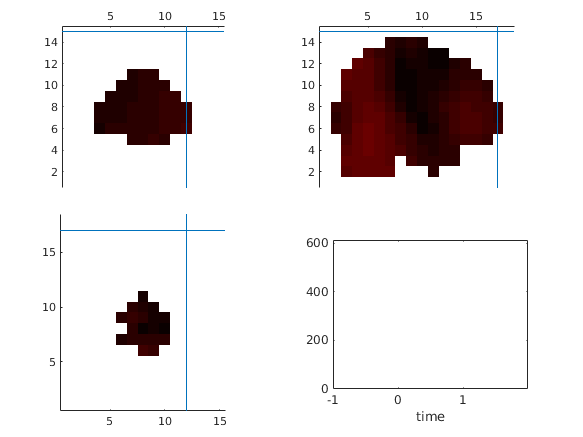


click left mouse button to reposition the cursor
click and hold right mouse button to update the position while moving the mouse
use the arrowkeys to navigate in the current axis
the call to "ft_sourceplot" took 0 seconds and required the additional allocation of an estimated 15 MB



cfg              = [];
cfg.method       = 'ortho';
cfg.funparameter = 'mom';
figure; ft_sourceplot(cfg, sourceProj);

Project sources on MRI

%% project sources on MRI and plot solution
mri = load('-mat', EEG.dipfit.mrifile);
mri = ft_volumereslice([], mri.mri);

the input is volume data with dimensions [181 217 181]
reslicing from [181 217 181] to [256 256 256]
the input is volume data with dimensions [256 256 256]
the input is volume data with dimensions [181 217 181]
selecting subvolume of 41.7%
reslicing and interpolating anatomy
interpolinterpolating 95.0
the call to "ft_sourceinterpolate" took 3 seconds and required the additional allocation of an estimated 1005 MB
the call to "ft_volumereslice" took 3 seconds and required the additional allocation of an estimated 1023 MB



cfg              = [];
cfg.downsample   = 2;
cfg.parameter    = 'pow';
source.oridimord = 'pos';
source.momdimord = 'pos';
sourceInt  = ft_sourceinterpolate(cfg, source , mri);

the input is volume data with dimensions [256 256 256]
the input is source data with 4050 brainordinates on a [15 18 15] grid
could not reshape "time" to the dimensions of the volume
updating homogenous coordinate transformation matrix
downsampling anatomy
downsampling inside
the call to "ft_volumedownsample" took 0 seconds and required the additional allocation of an estimated 654 MB
selecting subvolume of 19.9%
interpolating
interpolating 95.0
reslicing and interpolating pow
interpolating
interpolating 95.0
the call to "ft_sourceinterpolate" took 1 seconds and required the additional allocation of an estimated 783 MB


the input is source data with 2097152 brainordinates on a [128 128 128] grid
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
scaling anatomy to [0 1]
not using an atlas
not using a region-of-interest


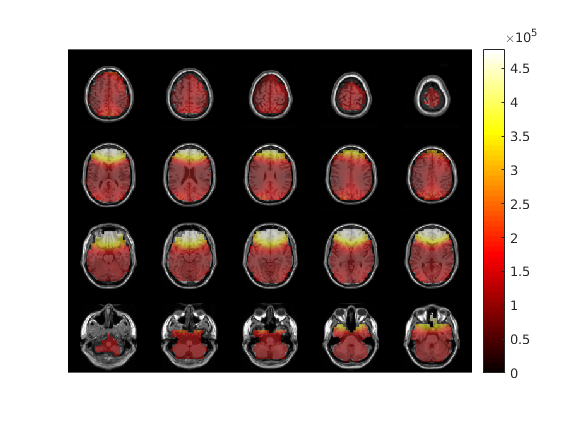

scaling anatomy
the call to "ft_sourceplot" took 1 seconds and required the additional allocation of an estimated 6 MB



cfg              = [];
cfg.method       = 'slice';
cfg.funparameter = 'pow';
ft_sourceplot(cfg, sourceInt);

## Source reconstruction on a surface

The code below generates a leadfield matrix for a realistic 3-D mesh in MNI space using minimal norm estimate (MNE). The previous section used eLoreta. Both MNE and eLoreta can perform source reconstruction at each latency (assuming you are using an EEG time series as input).

Note you need to choose the MNI BEM head model when selecting the head model in the DIPFIT settings.

Preparing the leadfieald surface: 

[ftVer, ftPath] = ft_version;
sourcemodel = ft_read_headshape(fullfile(ftPath, 'template', 'sourcemodel', 'cortex_8196.surf.gii'));


cfg           = [];
cfg.grid      = sourcemodel;    % source points
cfg.headmodel = vol.vol;        % volume conduction model
leadfield = ft_prepare_leadfield(cfg, dataAvg);

 In ft_checkconfig at line 130
 In ft_prepare_leadfield at line 136

using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
creating sourcemodel based on user specified dipole positions
using electrodes specified in the configuration
8190 dipoles inside, 6 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 1 seconds and required the additional allocation of an estimated 1 MB
computing leadfield
computing leadfield 8190/8190

the call to "ft_prepare_leadfield" took 24 seconds and required the additional allocation of an estimated 2 MB


Performaing surface source analysis:

cfg               = [];
cfg.method        = 'mne';
cfg.grid          = leadfield;
cfg.headmodel     = vol.vol;
cfg.mne.lambda    = 3;
cfg.mne.scalesourcecov = 'yes';
source            = ft_sourceanalysis(cfg, dataAvg);

the input is timelock data with 31 channels and 384 timebins


 In ft_checkconfig at line 130
 In ft_sourceanalysis at line 191

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
using precomputed leadfields
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
estimating current density distribution for repetition 1
using precomputed leadfields
computing the solution where the noise covariance is used for regularisation
scaling the source covariance
taking pseudo-inverse due to large condition number
The input data are real-valued, assuming sensor time-series: Computing the dipole moments
the call to "ft_sourceanalysis" took 1 seconds and required the additional allocation of an estimated

Plot global power:

the input is mesh data with 8196 vertices and 16384 triangles
the input is source data with 8196 brainordinates
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
not plotting anatomy
not using an atlas
not using a region-of-interest


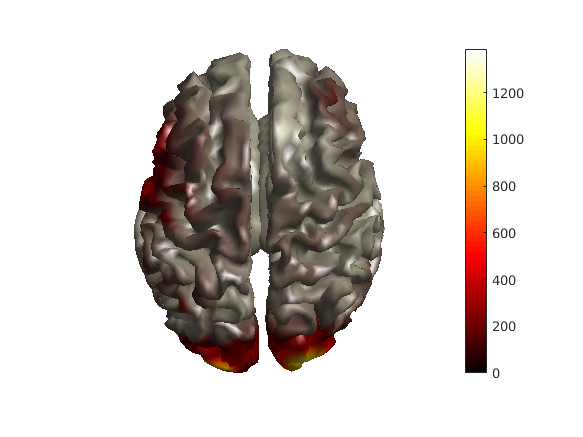

The source functional is defined on a triangulated surface, using the surface mesh description in the functional


 In ft_plot_mesh at line 189
 In ft_sourceplot at line 1266

the call to "ft_sourceplot" took 1 seconds and required the additional allocation of an estimated 2 MB


%% Surface source plot
cfg = [];
cfg.funparameter = 'pow';
cfg.maskparameter = 'pow';
cfg.method = 'surface';
cfg.latency = 0.4;
cfg.opacitylim = [0 200];
ft_sourceplot(cfg, source);

You may as well visually check the alignement of the source model mesh with the BEM head model mesh by overlaying the BEM mesh on the previous figure:

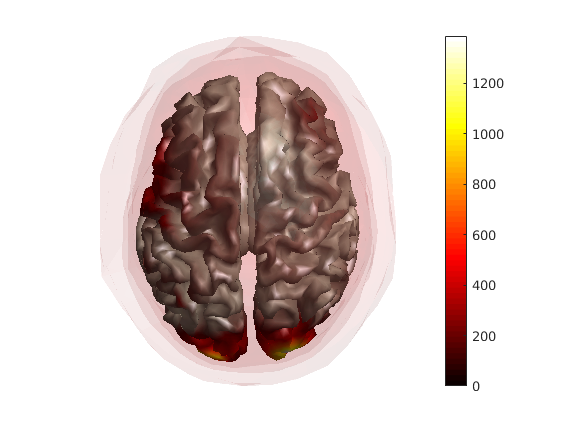

hold on; ft_plot_mesh(vol.vol.bnd(3), 'facecolor', 'red', 'facealpha', 0.05, 'edgecolor', 'none');
hold on; ft_plot_mesh(vol.vol.bnd(2), 'facecolor', 'red', 'facealpha', 0.05, 'edgecolor', 'none');
hold on; ft_plot_mesh(vol.vol.bnd(1), 'facecolor', 'red', 'facealpha', 0.05, 'edgecolor', 'none');